This algorithm uses a valid reverse test based on the Criss-Cross rule after complement, which is a complete version of Avis & Fukuda's method. It performs the reverse procedure along the Criss-Cross rule as depicted in Figure 3.1 of their paper but allow it to plot a spanning forest. If the arrangement is in the form Ax=b, then we denote is by matrix A_=[A|b].

All descrptions of this file can be used in the file "Symbolic incomplete CC rule _ spanning tree" which equipped with the valid reverse test before complement, and all detailed description of functions in this file apart from polting the graph can be found in "Symbolic reverse CC rule".

Below is an arrangement with 5 lines in R^2.

A_=[-1 0 -1
    0 -1 -1
    1 0 3
    0 1 3
    -1 1 -3]

A_ =     -1     0    -1
     0    -1    -1
     1     0     3
     0     1     3
    -1     1    -3


This is an example for multiple optimal dictionaries.

% A_=[1 3 4
%     5 1 5
%     3 2 2
%     -1 -3 1
%     -2 1 -1/2]

A_ =     1.0000    3.0000    4.0000
    5.0000    1.0000    5.0000
    3.0000    2.0000    2.0000
   -1.0000   -3.0000    1.0000
   -2.0000    1.0000   -0.5000


The following command will first construct a dictionary with an objective function in which each column in the row of the objective function has a coefficient of -1, except for the column of g, where the coefficient is 0. By changing the inequality (or outward normal of hyperplanes) to opposite direction, we can modify it to a primal feasible and hence optimal dictionary, and then apply the reverse procedure. Kindly noticed that the changing direction only working for the VE of an arrangement.

Additionally, if one needs to compute the coordinates of all vertices, the function "compute(vertex,A_)" provides the coordinates of vertices from the cobasis.

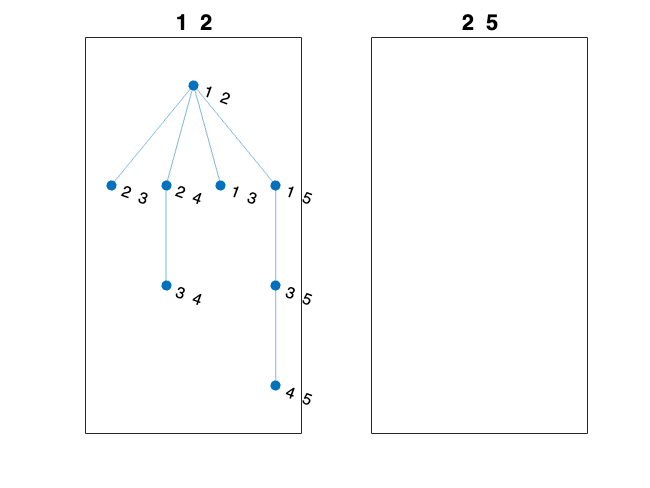

tic
[B,N,A]=dictionary_obj(A_);
vertex=reverse(B,N,A);

toc

Elapsed time is 1.593523 seconds.



result=comput(vertex,A_)

result =    -0.2857    1.4286
    0.0714   -0.3571
    0.4286    0.3571
    0.7857    1.0714
    1.1429   -0.7143


This function constructs the initial dictionary without an objective function from the coefficient matrix of the arrangement. It outputs the basis B, co-basis N, and coefficient matrix A to represent the initial dictionary x_B=Ax_N. We use 0 to represent g to ensure it is always the first entry of N, and we use "number of hyperplanes +1" to represent f to make it always the last entry of B.

function [B,N,A]=dictionary_obj(A_)
A_=sym(A_);
A0=A_(:,1:end-1);b=A_(:,end);
A_N=[];N=0;
[n,d]=size(A0);

for i=1:n
    if rank(A0(1:i,:))>rank(A0(1:i-1,:))
        A_N=[A_N;A0(i,:)];
        N=[N,i];
        if rank(A_N)==d
            break
        end 
    end
end

B=[setdiff(1:n,N(2:end)),n+1];

A=[[b(B(1:end-1)),zeros(n-d,d)]-A0(B(1:end-1),:)*inv(A_N)*[b(N(2:end)),-eye(d)];0,-ones(1,d)];
A=simplify(A);
for i=1:n-d
    if A(i,1)<0
        A(i,:)=-A(i,:);
    end
end
end

This function is based on the input initial dictionary x_B=Ax_N and the result of the function "findoptimal(B,N,A)" which generate all optimal dictionaries performs the reverse along the Criss-Cross rule from each optimal dictionary using the function "reversecrisscross(B,N,A)", gathering cobasis of those dictionaries that pass the lex-min test as output.

The input of "reverse(B,N,A)": 

    B: basis; N: cobasis; A: coefficient matrix; 

The output of "reverse(B,N,A)": 

   "vertex":  a matrix that listing exactly one cobasis for each vertex. The number of rows corresponds to the number of vertices in the arrangement. The spanning tree for corresponding optimal dictionary will be plot in this function.

function vertex=reverse(B,N,A)
optimal=findoptimal(B,N,A);
[op,~]=size(optimal);
vertex=[];

for h=1:op
    B=optimal{h,1};
    N=optimal{h,2};
    A=optimal{h,3};
    subplot(1,op,h)
    [reverseccrule,vertexes]=reversecrisscross(B,N,A);
    plot(reverseccrule,'Layout','layered')
    title(num2str(N(2:end)))
    vertex=[vertex;vertexes];
end
end

This function is based on the input dictionary x_B=Ax_N and performs the reverse along the Dual Bland's rule to find all optimal dictionaries.

The input of "findoptimal(B,N,A)": 

    B: basis; N: cobasis; A: coefficient matrix; 

The output of "findoptimal(B,N,A)": 

   "optimal":  a cell that listing one optimal dictionaries in each row in the order B,N,A for a dictionary x_B=Ax_N.

function optimal=findoptimal(B,N,A)
j=2;i=1;optimal={B,N,A};

B1=find(A(:,1)==0);
if length(B1)>1
subA=A(B1,:);subA(:,1)=[ones(length(B1)-1,1);0];
B1=B(B1); % subtract the sub dictionary out, and pivot parallel from the origion dictionary

while j<=length(N)+1
    if j<=length(N)
        reversedb=testdbreverse(B1,N,subA,i,j);
        if reversedb==1
            B2=B1(i);
            [B1,~,subA]=pivotrowcolumn(B1,N,subA,i,j);
            [B,N,A]=pivotrowcolumn(B,N,A,find(B==B2),j);
            optimal=[optimal;{B,N,A}];
            j=2;
            i=1;
        else
            [i,j]=increment(i,j,B1);
        end
    else
        [i,j]=selectdb(subA);
        if (isempty(i)==0 && isempty(j)==0)
            Bi=B1(i);Nj=N(j);
            [B1,~,subA]=pivotrowcolumn(B1,N,subA,i,j);
            [B,N,A]=pivotrowcolumn(B,N,A,find(B==Bi),j);
            i=find(B1==Nj);j=find(N==Bi);
            [i,j]=increment(i,j,B1);
        else
            break
        end
    end
end
end
end

This function is based on the input initial dictionary x_B=Ax_N and performs the reverse along the Criss-Cross rule.

The input of "reversecrisscross(B,N,A)": 

    B: basis; N: cobasis; A: coefficient matrix; 

The output of "reversecrisscross(B,N,A)": 

    "vertexes": a matrix that listing exactly one cobasis for each vertex. The number of rows corresponds to the number of vertices in the arrangement. 

    "reverseccrule": the information of spanning tree rooted at input N, each node of the spanning tree a cobasis of some dictionary.

function [reverseccrule,vertexes]=reversecrisscross(B,N,A)
vertexes=[];

lexmin=lexicography(B,N,A);
if lexmin==1
    vertexes=[vertexes;N(2:end)];
end

s={};t={}; % inaddition to the "Symbolic reverse CC rule", we use s to record those starting nodes and t to record those ending nodes, and construct the graph before exceed the function.
j=2;i=1;
while j<=length(N)+1
    if j<=length(N)
        reversecc=testccreverse(B,N,A,i,j);
        if reversecc==1
            s=[s,num2str(N(2:end))]; % let the cobasis before update be the startinging node.
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            t=[t,num2str(N(2:end))]; % let the cobasis after update be the ending node.
            lexmin=lexicography(B,N,A);
            if lexmin==1
                vertexes=[vertexes;N(2:end)];
            end
            j=2;i=1;
        else
            [i,j]=increment(i,j,B);
        end
    else
        [i,j]=selectcc(B,N,A);
        if (isempty(i)==0 && isempty(j)==0)
            Bi=B(i);Nj=N(j);
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            i=find(B==Nj);j=find(N==Bi);
            [i,j]=increment(i,j,B);
        else
            reverseccrule=graph(s,t); % based on the relation of staring and ending node, we construct a graph and plot out of the function.
            break
        end
    end
end
end

This function used to do pivot(B(i),N(j)) on the input dictionary x_B=Ax_N and update it, the input consist of all basis B, co-basis N, coefficient matrix A and the i,j-th entry in A, output are corresponding B,N,A for updated dictionary.

function [B,N,A]=pivotrowcolumn(B,N,A,i,j)
C=sym(zeros(size(A)));
for l=1:length(B) %compute remainders in the pivot.
    C(l,:)=A(l,:)-A(i,:)*A(l,j)/A(i,j);
end
C(i,:)=-A(i,:)/A(i,j); % compute the row in the pivot.
C(:,j)=A(:,j)/A(i,j);C(i,j)=1/A(i,j); % compute the column the the fixed entry in pivot.
N0=N;B0=B;
B(i)=N0(j);[B,I]=sort(B); % sort new B.
N(j)=B0(i);[N,J]=sort(N); % sort new N.
C=C(:,J);C=C(I,:);A=simplify(C); % permute the row and column of C in correspondence manner.
end

This function is designed to apply the Dual Bland's rule on a dictionary x_B=Ax_N and determine the fixed position of this rule as the i,j-th entry. If both i,j empty, the current dictionary is a terminal.

function [i,j]=selectdb(A)
i=[];j=[];
i=find(A(1:end-1,1)<0);
if isempty(i)==0
    temp=find(A(i,2:end)>0)+1;
    radio=min(-A(end,temp)./A(i,temp));
    j=temp(min(find(-A(end,temp)./A(i,temp)==radio)));
end
end

This function designed to test if the i,j-th entery on dictionary x_B=Ax_N a valid reverse pivot about the Dual Bland's rule, if yes, reversedb=1, otherwise =0.

function reversedb=testdbreverse(B,N,A,i,j)
reversedb=0;
temp=find(A(i,2:end)>0)+1;
radio=min(-A(end,temp)./A(i,temp));
if ismember(j,temp(find(-A(end,temp)./A(i,temp)==radio)))==1
    B0=find(B<N(j));
    if all(A(i,1)*A(B0,j)<=A(B0,1)*A(i,j)) && A(i,1)>0
        N0=find(N<B(i));N0(1)=[];
        if all(A(end,intersect(N0,find(A(i,:)<0))))
            reversedb=1;
        end
    end
end
end

This function is designed to apply the Criss-Cross rule on a dictionary x_B=Ax_N and determine the fixed position of this rule as the i,j-th entry. If one of i,j is empty, the current dictionary is a terminal.

function [i,j]=selectcc(B,N,A)
R=find(A(1:end-1,1)<0);S=find(A(end,2:end)>0)+1;
temp=min(union(B(R),N(S)));
if isempty(temp==1)
    i=[];j=[];
else
    if ismember(temp,N)==1
        j=find(N==temp);
        i=min(find(A(1:end-1,j)<0));
    else
        i=find(B==temp);j=min(find(A(i,2:end)>0)+1);
    end
end
end

This function designed to test if the i,j-th entery on dictionary x_B=Ax_N a valid reverse pivot about the Criss-Cross rule, if yes, reversecc=1, otherwise =0. This function is the only difference between this file and the file "Symbolic incomplete CC rule", at that file, the function is in a incomplete version demonstrated by Avis and Fukuda.

function reversecc=testccreverse(B,N,A,i,j)
reversecc=0;
if A(i,1)>0 && A(i,j)>0 && all(A(i,find(N(2:end)<B(i))+1)>=0)
    B0=find(B<N(j));
    N0=find(N<N(j));N0(1)=[];
    if all((A(B0,1)*A(i,j)-A(B0,j)*A(i,1))>=0) && all(A(end,j)*A(i,N0)-A(end,N0)*A(i,j)>=0) 
        if B(i)<N(j)
            if A(end,j)<=0
                reversecc=1;
            end
        else
            reversecc=1;
        end
    end
end

if A(end,j)<0 && A(i,j)<0 && all(A(find(B(1:end-1)<N(j)),j)<=0)
    B0=find(B<B(i)); % those in B and less than B(i)=s
    N0=find(N<B(i));N0(1)=[]; % those in N and less than B(i)=s, exclude the first column, the constant
    if all(A(B0,j)*A(i,1)-A(B0,1)*A(i,j)>=0) && all(A(end,N0)*A(i,j)-A(end,j)*A(i,N0)>=0) 
        if N(j)<B(i)
            if A(i,1)>=0
                reversecc=1;
            end
        else
            reversecc=1;
        end
    end
end
end

This function designed to test if the current dictionary pass the lex-min test, if yes, lexmin=1, otherwise =0. Kindly noticed that this is different from the no objective function case, since the last row (the row of objective function) need to be ignored.

function lexmin=lexicography(B,N,A)
B0=B(find(A(1:end-1,1)==0));
lexmin=1;
if isempty(B0)==1
    lexmin=1;
else
    for i=length(B0):-1:1
        N0=find(N(2:end)<B0(i))+1;
        if isempty(N0)==0
            if any(A(find(B==B0(i)),N0)~=0)==1
                lexmin=0;
                break
            end
        else
            break
        end
    end
end

end

This function computes all vertices after enumeration based on the given coefficient matrix of the arrangement and the set of indexes N to obtain coordinate of all vertices in the arranegment.

function result=comput(result_dic,A_)
[ver,~]=size(result_dic);[~,n_]=size(A_);A_=[A_;-eye(n_)];A_=A_(1:end-1,:);
vertex=[];
for i=1:ver
    vert=inv(A_(result_dic(i,:),1:end-1))*A_(result_dic(i,:),end);
    vertex=[vertex;transpose(vert)];
end
result=sortrows(vertex);
end

This function update [i,j] to the next candidate with a size of dictionary. Kindly noticed that this is different from the no objective function case, since the last row (the row of objective function) need to be ignored.

function [i,j]=increment(i,j,B)
i=i+1;
if i==length(B) % use B to verify if it go to the row of objective function, if yes, go next column and the first row.
    i=1;j=j+1;
end
end